# Actividad Raices de ecuaciones

### *Ecuación 1*

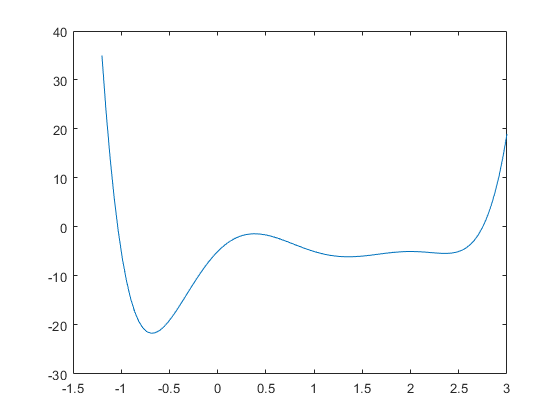

f = @(x) 2.*x.^6 - 13.*x.^5 + 26.*x.^4 - 7.*x.^3 - 28.*x.^2 + 20.*x - 5; %revisar ecuacion
fp = @(x) 12.*x.^5 - 65.*x.^4 + 104.*x.^3 - 21.*x.^2 - 56.*x -20;

h = 1e-6;
fp =@(x) (f(x+0.5*h)-f(x-0.5*h))/h;

x = linspace(-1.2,3);
plot(x, f(x))


xa = -1;    %establecer valores
xb = 5;
errmax = 0.1;
[xr, fr, err] = biseccion(f, xa, xb, errmax);

xa: -1  xb: 5  xm: 2  fa: -5  fb: 5395  fm: -5  error: 150
xa: 2  xb: 5  xm: 3.5  fa: -5  fb: 5395  fm: 172.1875  error: 42.8571
xa: 2  xb: 3.5  xm: 2.75  fa: -5  fb: 172.1875  fm: 0.075684  error: 27.2727
xa: 2  xb: 2.75  xm: 2.375  fa: -5  fb: 0.075684  fm: -5.3875  error: 15.7895
xa: 2.375  xb: 2.75  xm: 2.5625  fa: -5.3875  fb: 0.075684  fm: -4.4359  error: 7.3171
xa: 2.5625  xb: 2.75  xm: 2.6562  fa: -4.4359  fb: 0.075684  fm: -2.8352  error: 3.5294
xa: 2.6562  xb: 2.75  xm: 2.7031  fa: -2.8352  fb: 0.075684  fm: -1.576  error: 1.7341
xa: 2.7031  xb: 2.75  xm: 2.7266  fa: -1.576  fb: 0.075684  fm: -0.80366  error: 0.8596
xa: 2.7266  xb: 2.75  xm: 2.7383  fa: -0.80366  fb: 0.075684  fm: -0.37796  error: 0.42796
xa: 2.7383  xb: 2.75  xm: 2.7441  fa: -0.37796  fb: 0.075684  fm: -0.15471  error: 0.21352
xa: 2.7441  xb: 2.75  xm: 2.7471  fa: -0.15471  fb: 0.075684  fm: -0.040413  error: 0.10665
xa: 2.7471  xb: 2.75  xm: 2.7485  fa: -0.040413  fb: 0.075684  fm: 0.017409  error: 0.053295

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 2.7485  f(x) = 0.017409  Error:0.053295%


[xr, fr, err] = falsa_posicion(f, 2, 3, errmax);

xa: 2  xb: 3  xm: 2.2083  fa: -5  fb: 19  fm: -5.2168  error: 9.434
xa: 2.2083  xb: 3  xm: 2.3789  fa: -5.2168  fb: 19  fm: -5.3854  error: 7.1689
xa: 2.3789  xb: 3  xm: 2.516  fa: -5.3854  fb: 19  fm: -4.8854  error: 5.4519
xa: 2.516  xb: 3  xm: 2.615  fa: -4.8854  fb: 19  fm: -3.6713  error: 3.7852
xa: 2.615  xb: 3  xm: 2.6774  fa: -3.6713  fb: 19  fm: -2.3119  error: 2.3284
xa: 2.6774  xb: 3  xm: 2.7124  fa: -2.3119  fb: 19  fm: -1.2835  error: 1.2903
xa: 2.7124  xb: 3  xm: 2.7306  fa: -1.2835  fb: 19  fm: -0.66111  error: 0.66655
xa: 2.7306  xb: 3  xm: 2.7396  fa: -0.66111  fb: 19  fm: -0.32716  error: 0.33069
xa: 2.7396  xb: 3  xm: 2.744  fa: -0.32716  fb: 19  fm: -0.15867  error: 0.16062
xa: 2.744  xb: 3  xm: 2.7462  fa: -0.15867  fb: 19  fm: -0.076193  error: 0.077192


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 2.7462  f(x) = -0.076193  Error:0.077192%


[xr, fr, err] = secante(f, xa, xb, errmax);

xa: -1  f1: -1  xb: 5  f2: 5395  x3: -0.99444  f3: -5.6905  error: 602.7933
xa: 5  f1: 5  xb: -0.99444  f2: -5.6905  x3: -0.98813  f3: -6.4528  error: 0.6392
xa: -0.99444  f1: -0.99444  xb: -0.98813  f2: -6.4528  x3: -1.0416  f3: 0.79657  error: 5.1334
xa: -0.98813  f1: -0.98813  xb: -1.0416  f2: 0.79657  x3: -1.0357  f3: -0.091675  error: 0.56727
xa: -1.0416  f1: -1.0416  xb: -1.0357  f2: -0.091675  x3: -1.0363  f3: -0.0010927  error: 0.058513


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = -1.0363  f(x) = -0.0010927  Error:0.058513%


[xr, fr,err] = newton_raphson(f, fp, xa, errmax);

x: -1.0397  f: -1.0397  error: 3.8168
x: -1.0364  f: -1.0364  error: 0.32048
x: -1.0363  f: -1.0363  error: 0.0024376


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = -1.0363  f(x) = 2.1737e-07  Error:0.0024376%


%implementar newton raphson

### *Ecuación 2*

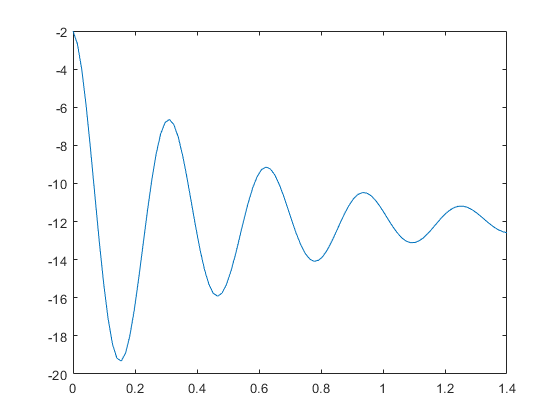

f = @(x) 10.*exp(-2*x) .* cos(20*x) - 12;  %revisar ecuacion
%fp = @(x) (10)*(-2.*exp(-2*x) * cos(20.*x) - 20 .* exp(-2*x) * sin(20*x));

h = 1e-6;
fp =@(x) (f(x+0.5*h)-f(x-0.5*h))/h;

x = linspace(0,1.4);
plot(x, f(x))


xa = 1;   %establecer valores
xb = -1;
errmax = 0.1;
[xr, fr, err] = biseccion(f, xa, xb, errmax);

xa: 1  xb: -1  xm: 0  fa: -11.4477  fb: 18.1534  fm: -2  error: 4.503599627370496e+17
xa: 0  xb: -1  xm: -0.5  fa: -2  fb: 18.1534  fm: -34.8083  error: 100
xa: -0.5  xb: -1  xm: -0.75  fa: -34.8083  fb: 18.1534  fm: -46.0469  error: 33.3333
xa: -0.75  xb: -1  xm: -0.875  fa: -46.0469  fb: 18.1534  fm: 0.6279  error: 14.2857
xa: -0.75  xb: -0.875  xm: -0.8125  fa: -46.0469  fb: 0.6279  fm: -55.5048  error: 7.6923
xa: -0.8125  xb: -0.875  xm: -0.84375  fa: -55.5048  fb: 0.6279  fm: -33.2388  error: 3.7037
xa: -0.84375  xb: -0.875  xm: -0.85938  fa: -33.2388  fb: 0.6279  fm: -17.083  error: 1.8182
xa: -0.85938  xb: -0.875  xm: -0.86719  fa: -17.083  fb: 0.6279  fm: -8.3206  error: 0.9009
xa: -0.86719  xb: -0.875  xm: -0.87109  fa: -8.3206  fb: 0.6279  fm: -3.8562  error: 0.44843
xa: -0.87109  xb: -0.875  xm: -0.87305  fa: -3.8562  fb: 0.6279  fm: -1.6149  error: 0.22371
xa: -0.87305  xb: -0.875  xm: -0.87402  fa: -1.6149  fb: 0.6279  fm: -0.49349  error: 0.11173
xa: -0.87402  xb: -0.875 

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = -0.87451  f(x) = 0.067239  Error:0.055835%


[xr, fr, err] = falsa_posicion(f, xa, xb, errmax);

xa: 1  xb: -1  xm: 0.22653  fa: -11.4477  fb: 18.1534  fm: -13.1486  error: 341.433
xa: 0.22653  xb: -1  xm: -0.28868  fa: -13.1486  fb: 18.1534  fm: 3.5498  error: 178.473
xa: 0.22653  xb: -0.28868  xm: -0.17915  fa: -13.1486  fb: 3.5498  fm: -24.9372  error: 61.1353
xa: -0.17915  xb: -0.28868  xm: -0.27503  fa: -24.9372  fb: 3.5498  fm: 0.29127  error: 34.8607
xa: -0.17915  xb: -0.27503  xm: -0.27392  fa: -24.9372  fb: 0.29127  fm: -0.0088762  error: 0.4041
xa: -0.27392  xb: -0.27503  xm: -0.27396  fa: -0.0088762  fb: 0.29127  fm: 6.6793e-05  error: 0.011949


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = -0.27396  f(x) = 6.6793e-05  Error:0.011949%


[xr, fr, err] = secante(f, xa, xb, errmax) %

xa: 1  f1: 1  xb: -1  f2: 18.1534  x3: 0.22653  f3: -13.1486  error: 541.433
xa: -1  f1: -1  xb: 0.22653  f2: -13.1486  x3: -0.28868  f3: 3.5498  error: 178.473
xa: 0.22653  f1: 0.22653  xb: -0.28868  f2: 3.5498  x3: -0.17915  f3: -24.9372  error: 61.1353
xa: -0.28868  f1: -0.28868  xb: -0.17915  f2: -24.9372  x3: -0.27503  f3: 0.29127  error: 34.8607
xa: -0.17915  f1: -0.17915  xb: -0.27503  f2: 0.29127  x3: -0.27392  f3: -0.0088762  error: 0.4041
xa: -0.27503  f1: -0.27503  xb: -0.27392  f2: -0.0088762  x3: -0.27396  f3: 6.6793e-05  error: 0.011949


xr = -0.2740

fr = 6.6793e-05

err = 0.0119

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%") %

x = -0.27396  f(x) = 6.6793e-05  Error:0.011949%


[xr, fr,err] = newton_raphson(f, fp, xa, errmax);

x: 0.55655  f: 0.55655  error: 79.6775
x: 0.73651  f: 0.73651  error: 24.4335
x: 0.36195  f: 0.36195  error: 103.4832
x: 0.25343  f: 0.25343  error: 42.8219
x: 0.34449  f: 0.34449  error: 26.4334
x: 0.22425  f: 0.22425  error: 53.6183
x: 0.32982  f: 0.32982  error: 32.0082
x: 0.15998  f: 0.15998  error: 106.1563
x: 0.99945  f: 0.99945  error: 83.9929
x: 0.5554  f: 0.5554  error: 79.9521
x: 0.73515  f: 0.73515  error: 24.4507
x: 0.37104  f: 0.37104  error: 98.1298
x: 0.26044  f: 0.26044  error: 42.4687
x: 0.35326  f: 0.35326  error: 26.2756
x: 0.24221  f: 0.24221  error: 45.8513
x: 0.33506  f: 0.33506  error: 27.7117
x: 0.19113  f: 0.19113  error: 75.3064
x: 0.3704  f: 0.3704  error: 48.4002
x: 0.26008  f: 0.26008  error: 42.4187
x: 0.35274  f: 0.35274  error: 26.2697
x: 0.24136  f: 0.24136  error: 46.1466
x: 0.33454  f: 0.33454  error: 27.8531
x: 0.18863  f: 0.18863  error: 77.3513
x: 0.37927  f: 0.37927  error: 50.2639
x: 0.26335  f: 0.26335  error: 44.0173
x: 0.35774  f: 0.35774  err

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = -0.27396  f(x) = -6.8759e-09  Error:0.00069851%


%implementar newton raphson

### Ecuación 3

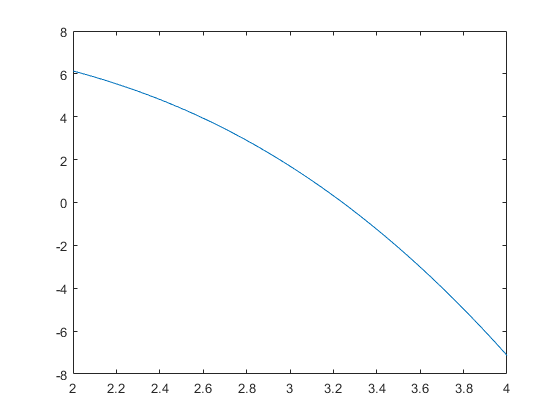

f = @(x) 7.*(sqrt(x.^3 + 2)) - 4.*x.^2;   %revisar ecuacion
fp = @(x) (21.*x.^2) / (2.*(sqrt(x.^3 + 2)));

h = 1e-6;
fp =@(x) (f(x+0.5*h)-f(x-0.5*h))/h;

x = linspace(2,4);
plot(x, f(x))


xa = -1;    %establecer valores
xb = 4;
errmax = 0.1;
[xr, fr, err] = biseccion(f, xa, xb, errmax);

xa: -1  xb: 4  xm: 1.5  fa: 3  fb: -7.1317  fm: 7.2288  error: 166.6667
xa: 1.5  xb: 4  xm: 2.75  fa: 7.2288  fb: -7.1317  fm: 3.1723  error: 45.4545
xa: 2.75  xb: 4  xm: 3.375  fa: 3.1723  fb: -7.1317  fm: -1.0459  error: 18.5185
xa: 2.75  xb: 3.375  xm: 3.0625  fa: 3.1723  fb: -1.0459  fm: 1.2841  error: 10.2041
xa: 3.0625  xb: 3.375  xm: 3.2188  fa: 1.2841  fb: -1.0459  fm: 0.17616  error: 4.8544
xa: 3.2188  xb: 3.375  xm: 3.2969  fa: 0.17616  fb: -1.0459  fm: -0.42042  error: 2.3697
xa: 3.2188  xb: 3.2969  xm: 3.2578  fa: 0.17616  fb: -0.42042  fm: -0.11854  error: 1.199
xa: 3.2188  xb: 3.2578  xm: 3.2383  fa: 0.17616  fb: -0.11854  fm: 0.029704  error: 0.60314
xa: 3.2383  xb: 3.2578  xm: 3.248  fa: 0.029704  fb: -0.11854  fm: -0.044195  error: 0.30066
xa: 3.2383  xb: 3.248  xm: 3.2432  fa: 0.029704  fb: -0.044195  fm: -0.0071894  error: 0.15056
xa: 3.2383  xb: 3.2432  xm: 3.2407  fa: 0.029704  fb: -0.0071894  fm: 0.011271  error: 0.075335


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 3.2407  f(x) = 0.011271  Error:0.075335%


[xr, fr, err] = falsa_posicion(f, xa, xb, errmax);

xa: -1  xb: 4  xm: 0.4805  fa: 3  fb: -7.1317  fm: 9.2468  error: 308.1177
xa: 0.4805  xb: 4  xm: 2.4675  fa: 9.2468  fb: -7.1317  fm: 4.5275  error: 80.527
xa: 2.4675  xb: 4  xm: 3.0626  fa: 4.5275  fb: -7.1317  fm: 1.2835  error: 19.4311
xa: 3.0626  xb: 4  xm: 3.2056  fa: 1.2835  fb: -7.1317  fm: 0.27398  error: 4.4602
xa: 3.2056  xb: 4  xm: 3.235  fa: 0.27398  fb: -7.1317  fm: 0.05473  error: 0.90854
xa: 3.235  xb: 4  xm: 3.2408  fa: 0.05473  fb: -7.1317  fm: 0.010786  error: 0.17978
xa: 3.2408  xb: 4  xm: 3.2419  fa: 0.010786  fb: -7.1317  fm: 0.00212  error: 0.035364


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 3.2419  f(x) = 0.00212  Error:0.035364%


[xr, fr, err] = secante(f, xa, xb, errmax)

xa: -1  f1: -1  xb: 4  f2: -7.1317  x3: 0.4805  f3: 9.2468  error: 732.471
xa: 4  f1: 4  xb: 0.4805  f2: 9.2468  x3: 2.4675  f3: 4.5275  error: 80.527
xa: 0.4805  f1: 0.4805  xb: 2.4675  f2: 4.5275  x3: 4.3737  f3: -11.7281  error: 43.5833
xa: 2.4675  f1: 2.4675  xb: 4.3737  f2: -11.7281  x3: 2.9984  f3: 1.7064  error: 45.8674
xa: 4.3737  f1: 4.3737  xb: 2.9984  f2: 1.7064  x3: 3.1731  f3: 0.51155  error: 5.5051
xa: 2.9984  f1: 2.9984  xb: 3.1731  f2: 0.51155  x3: 3.2479  f3: -0.042954  error: 2.3026
xa: 3.1731  f1: 3.1731  xb: 3.2479  f2: -0.042954  x3: 3.2421  f3: 0.00093472  error: 0.17869
xa: 3.2479  f1: 3.2479  xb: 3.2421  f2: 0.00093472  x3: 3.2422  f3: 1.6428e-06  error: 0.0038055


xr = 3.2422

fr = 1.6428e-06

err = 0.0038

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 3.2422  f(x) = 1.6428e-06  Error:0.0038055%


[xr, fr,err] = newton_raphson(f, fp, xa, errmax) %

x: -1.1622  f: -1.1622  error: 13.9535
x: -1.1359  f: -1.1359  error: 2.3075
x: -1.1343  f: -1.1343  error: 0.14468
x: -1.1343  f: -1.1343  error: 0.00046365


xr = -1.1343

fr = -1.4661e-09

err = 4.6365e-04

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%") %

x = -1.1343  f(x) = -1.4661e-09  Error:0.00046365%


%implementar newton raphson

### Ecuación 4

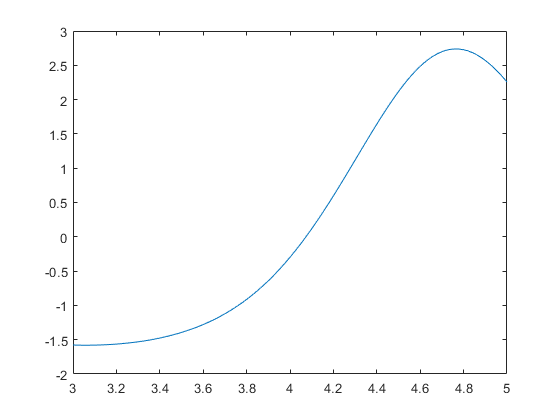

f = @(x) x.*exp(-2*cos(x).^2) - 2;  %revisar ecuacion
fp = @(x) 2.*exp(-2*cos(x)^2) * x.*sin(2.*x) + exp(-2*cos(x)^2);

h = 1e-6;
fp =@(x) (f(x+0.5*h)-f(x-0.5*h))/h;

x = linspace(3,5);
plot(x, f(x))


xa = -1;     %establecer valores
xb = 7;
errmax = 0.1;
[xr, fr, err] = biseccion(f, xa, xb, errmax);

xa: -1  xb: 7  xm: 3  fa: -2.5577  fb: 0.24605  fm: -1.5775  error: 133.3333
xa: 3  xb: 7  xm: 5  fa: -1.5775  fb: 0.24605  fm: 2.2568  error: 40
xa: 3  xb: 5  xm: 4  fa: -1.5775  fb: 2.2568  fm: -0.29802  error: 25
xa: 4  xb: 5  xm: 4.5  fa: -0.29802  fb: 2.2568  fm: 2.1173  error: 11.1111
xa: 4  xb: 4.5  xm: 4.25  fa: -0.29802  fb: 2.1173  fm: 0.8546  error: 5.8824
xa: 4  xb: 4.25  xm: 4.125  fa: -0.29802  fb: 0.8546  fm: 0.23181  error: 3.0303
xa: 4  xb: 4.125  xm: 4.0625  fa: -0.29802  fb: 0.23181  fm: -0.046717  error: 1.5385
xa: 4.0625  xb: 4.125  xm: 4.0938  fa: -0.046717  fb: 0.23181  fm: 0.089304  error: 0.76336
xa: 4.0625  xb: 4.0938  xm: 4.0781  fa: -0.046717  fb: 0.089304  fm: 0.020457  error: 0.38314
xa: 4.0625  xb: 4.0781  xm: 4.0703  fa: -0.046717  fb: 0.020457  fm: -0.013342  error: 0.19194
xa: 4.0703  xb: 4.0781  xm: 4.0742  fa: -0.013342  fb: 0.020457  fm: 0.0035051  error: 0.095877


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 4.0742  f(x) = 0.0035051  Error:0.095877%


[xr, fr, err] = falsa_posicion(f, xa, xb, errmax);

xa: -1  xb: 7  xm: 6.298  fa: -2.5577  fb: 0.24605  fm: -1.1473  error: 115.8782
xa: 6.298  xb: 7  xm: 6.876  fa: -1.1473  fb: 0.24605  fm: -0.26263  error: 8.4071
xa: 6.876  xb: 7  xm: 6.94  fa: -0.26263  fb: 0.24605  fm: -0.020135  error: 0.92229
xa: 6.94  xb: 7  xm: 6.9446  fa: -0.020135  fb: 0.24605  fm: -0.0013612  error: 0.06532


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 6.9446  f(x) = -0.0013612  Error:0.06532%


[xr, fr, err] = secante(f, xa, xb, errmax)

xa: -1  f1: -1  xb: 7  f2: 0.24605  x3: 6.298  f3: -1.1473  error: 11.1472
xa: 7  f1: 7  xb: 6.298  f2: -1.1473  x3: 6.876  f3: -0.26263  error: 8.4071
xa: 6.298  f1: 6.298  xb: 6.876  f2: -0.26263  x3: 7.0476  f3: 0.48633  error: 2.435
xa: 6.876  f1: 6.876  xb: 7.0476  f2: 0.48633  x3: 6.9362  f3: -0.035823  error: 1.6065
xa: 7.0476  f1: 7.0476  xb: 6.9362  f2: -0.035823  x3: 6.9438  f3: -0.0043652  error: 0.1101
xa: 6.9362  f1: 6.9362  xb: 6.9438  f2: -0.0043652  x3: 6.9449  f3: 4.8711e-05  error: 0.015275


xr = 6.9449

fr = 4.8711e-05

err = 0.0153

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 6.9449  f(x) = 4.8711e-05  Error:0.015275%


[xr, fr,err] = newton_raphson(f, fp, xa, errmax)

x: 0.627  f: 0.627  error: 259.4884
x: 3.7282  f: 3.7282  error: 83.182
x: 4.2716  f: 4.2716  error: 12.7216
x: 4.0881  f: 4.0881  error: 4.4883
x: 4.0736  f: 4.0736  error: 0.35685
x: 4.0734  f: 4.0734  error: 0.0040751


xr = 4.0734

fr = 9.5106e-08

err = 0.0041

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 4.0734  f(x) = 9.5106e-08  Error:0.0040751%


%implementar newton raphson

#### *Función método bisección*

function [xr, fr, err] = biseccion(f, xa, xb, errmax)
% Función que resuelve una ecuación de una variable por 
% el método de bisección.
%
% Entradas:
%   f         Función que define la ecuación a resolver.
%   xa        Valor inicial del rango de la ecuación.
%   xb        Valor final del rango de la ecuación.
%   errmax    Máximo error permitido para la solución.
%
% Salidas:
%   xr        Raíz de la ecuación encontrada.
%   fr        Valor de la ecuación en la raíz encontrada.
%   err       Error porcentual de la última iteración.

% Verifica que los parámetros de entrada sean válidos.
if nargin ~= 4
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(xa) || ~isnumeric(xa)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(xb) || ~isnumeric(xb)
    error('El valor xb debe ser numérico y escalar.')
end

if ~isscalar(errmax) || ~isnumeric(errmax) || errmax <= 0
    error('El valor errmax debe ser numérico, escalar y mayor a cero.')
end

% Evalúa la función en los puntos iniciales.
fa = f(xa);
fb = f(xb);

% Verifica si los valores iniciales son una solución.
if fa == 0
    xr = xa;
    fr = 0;
    err = 0;
    return 
end

if fb == 0
    xr = xb;
    fr = 0;
    err = 0;
    return 
end

% Verifica que entre los valores dados haya una solución.
if fa*fb > 0
    error('Valores iniciales no válidos.')
end

% Algoritmo de bisección.
err = 100*errmax;
xm = xa;
while err > errmax
    
    % Valor anterior de xm
    xma = xm;
    
    % Nuevo valor de xm
    xm = (xa + xb)/2;
    fm = f(xm);
    
    % Calcula el error actual.
    err = 100*(abs(xm - xma)/max([abs(xm), eps]));
    
    % Despliega los valores actuales.
    disp("xa: " + xa + "  xb: " + xb + "  xm: " + xm + ...
        "  fa: " + fa + "  fb: " + fb + "  fm: " + fm + "  error: " + err)
    
    % Actualiza los límites del intervalo.
    if fa*fm < 0
        % En este caso, xb se mueve a la posición xm.
        xb = xm;
        fb = fm;
    elseif fb*fm < 0
        % En este caso, xa se mueve a la posición xm.
        xa = xm;
        fa = fm;
    else
        % En este caso tenemos una solución en xm.
        err = 0;
    end     
    
end

% Guarda el resultado en las variables de salida.
xr = xm;
fr = fm;
end

#### *Función Falsa Posición*

function [xr, fr, err] = falsa_posicion(f, xa, xb, errmax)
% Función que resuelve una ecuación de una variable por 
% el método de falsa posición.
%
% Entradas:
%   f         Función que define la ecuación a resolver.
%   xa        Valor inicial del rango de la ecuación.
%   xb        Valor final del rango de la ecuación.
%   errmax    Máximo error permitido para la solución.
%
% Salidas:
%   xr        Raíz de la ecuación encontrada.
%   fr        Valor de la ecuación en la raíz encontrada.
%   err       Error porcentual de la última iteración.

% Verifica que los parámetros de entrada sean válidos.
if nargin ~= 4
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(xa) || ~isnumeric(xa)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(xb) || ~isnumeric(xb)
    error('El valor xb debe ser numérico y escalar.')
end

if ~isscalar(errmax) || ~isnumeric(errmax) || errmax <= 0
    error('El valor errmax debe ser numérico, escalar y mayor a cero.')
end

% Evalúa la función en los puntos iniciales.
fa = f(xa);
fb = f(xb);

% Verifica si los valores iniciales son una solución.
if fa == 0
    xr = xa;
    fr = 0;
    err = 0;
    return 
end

if fb == 0
    xr = xb;
    fr = 0;
    err = 0;
    return 
end

% Verifica que entre los valores dados haya una solución.
if fa*fb > 0
    error('Valores iniciales no válidos.')
end

% Algoritmo de falsa posición.
err = 100*errmax;
xm = xa;
while err > errmax
    
    % Valor anterior de xm
    xma = xm;
    
    % Nuevo valor de xm
    xm = xb - (xb-xa) * fb / (fb - fa);
    fm = f(xm);
    
    % Calcula el error actual.
    err = 100*(abs(xm - xma)/max([abs(xm), eps]));
    
    % Despliega los valores actuales.
    disp("xa: " + xa + "  xb: " + xb + "  xm: " + xm + ...
        "  fa: " + fa + "  fb: " + fb + "  fm: " + fm + "  error: " + err)
    
    % Actualiza los límites del intervalo.
    if fa*fm < 0
        % En este caso, xb se mueve a la posición xm.
        xb = xm;
        fb = fm;
    elseif fb*fm < 0
        % En este caso, xa se mueve a la posición xm.
        xa = xm;
        fa = fm;
    else
        % En este caso tenemos una solución en xm.
        err = 0;
    end     
    
end

% Guarda el resultado en las variables de salida.
xr = xm;
fr = fm;
end


#### *Funcion metodo secante*

function [xr, fr, err] = secante(f, xa, xb, errmax)
% Función que resuelve una ecuación de una variable por 
% el método de la secante.
%
% Entradas:
%   f         Función que define la ecuación a resolver.
%   xa        Primer valor inicial.
%   xb        Segundo valor inicial.
%   errmax    Máximo error permitido para la solución.
%
% Salidas:
%   xr        Raíz de la ecuación encontrada.
%   fr        Valor de la ecuación en la raíz encontrada.
%   err       Error porcentual de la última iteración.

% Verifica que los parámetros de entrada sean válidos.
if nargin ~= 4
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(xa) || ~isnumeric(xa)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(xa) || ~isnumeric(xb)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(errmax) || ~isnumeric(errmax) || errmax <= 0
    error('El valor errmax debe ser numérico, escalar y mayor a cero.')
end

% Evalúa la función en los puntos iniciales.
f1 = f(xa);
f2 = f(xb);

% Verifica si los valores iniciales son una solución.
if f1 == 0
    xr = xa;
    fr = 0;
    err = 0;
    return 
end

if f2 == 0
    xr = xb;
    fr = 0;
    err = 0;
    return 
end

% Algoritmo
err = 100*errmax;
while err > errmax
            
    % Intersección de la recta secante con el eje x
    x3 = xb - ((xb-xa)/(f2-f1))*f2;
    f3 = f(x3);
    
    % Calcula el error actual.
    err = 100*(abs(x3 - xb)/max([abs(x3), eps]));
    
    % Despliega los valores actuales.
    disp("xa: " + xa + "  f1: " + xa + ...
        "  xb: " + xb + "  f2: " + f2 + ...
        "  x3: " + x3 + "  f3: " + f3 + ...
        "  error: " + err)
    
    % Actualiza los valores de x
    xa = xb;
    f1 = f2;
    xb = x3;
    f2 = f3;    
end

% Guarda el resultado en las variables de salida.
xr = xb;
fr = f2;
end

#### *Función método Newton-Raphson*

function [xr, fr, err] = newton_raphson(f, fp, x, errmax)

if nargin ~= 4
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(x) || ~isnumeric(x)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(x)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(errmax) || ~isnumeric(errmax) || errmax <= 0
    error('El valor errmax debe ser numérico, escalar y mayor a cero.')
end

xa = x + errmax*100;
err =  100 * abs((x - xa) / x);
while  err > errmax
    
    xa = x;
    x = xa - (f(xa)) / fp(xa);
    err =  100 * abs((x - xa) / x);
    
    disp("x: " + x + "  f: " + x + ...
        "  error: " + err)
end

xr = x;
fr = f(xr);

end